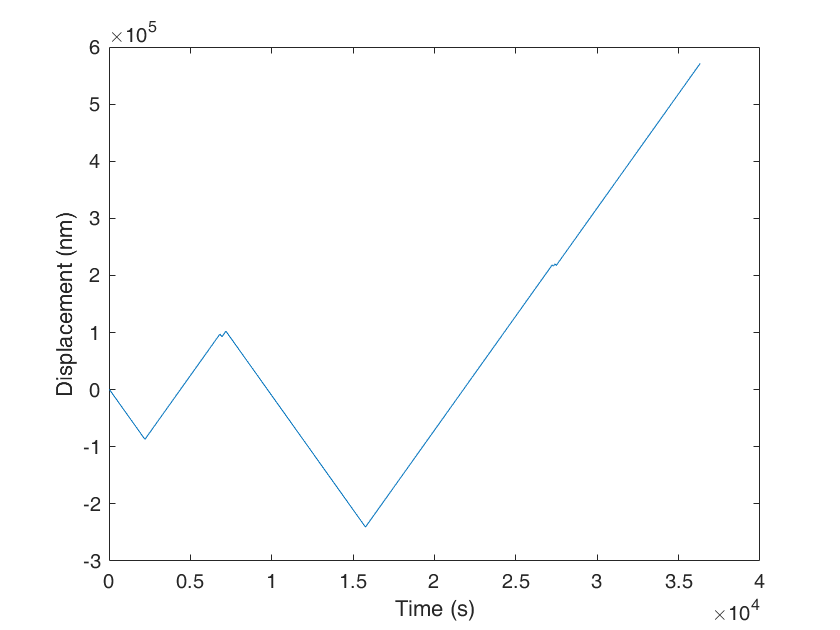

motorPar.eps0=0.01/60;%single motor unbinding rate s^-1
motorPar.pi0 =0.4/60; %single motor binding rate s^-1
motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.Nplus=2;%total number of plus motors 
motorPar.Nminus=2;%total number of bound plus motors 
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s

motorState=motorPar;
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 1000;

%motorDynamics = lipowskiModel(motorState)

[dynamics] = lipowskiSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

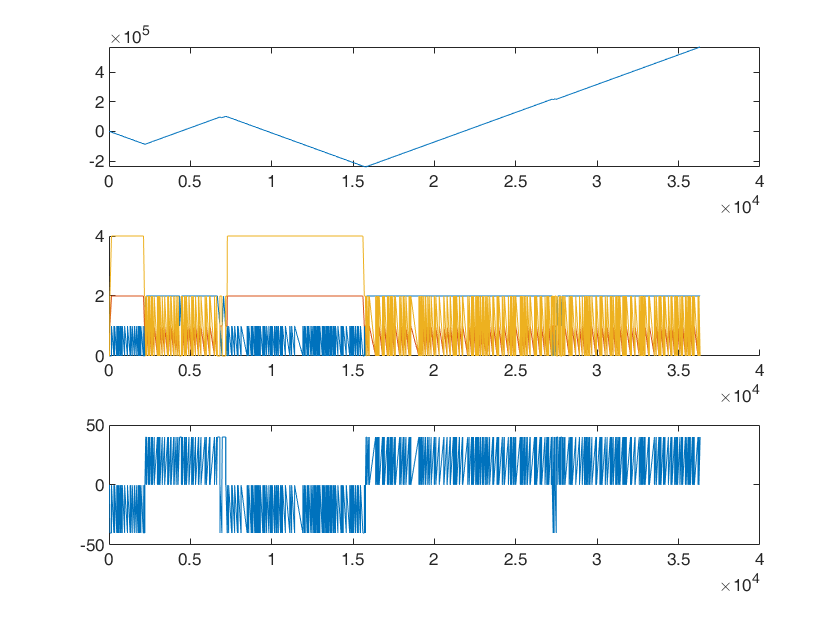


subplot(3,1,1);
plot(t,x);
subplot(3,1,2);
hold all;
plot(t,nPlus);
plot(t,nMinus);
plot(t,nMinus+nMinus);
subplot(3,1,3);
plot(t,vCargo);

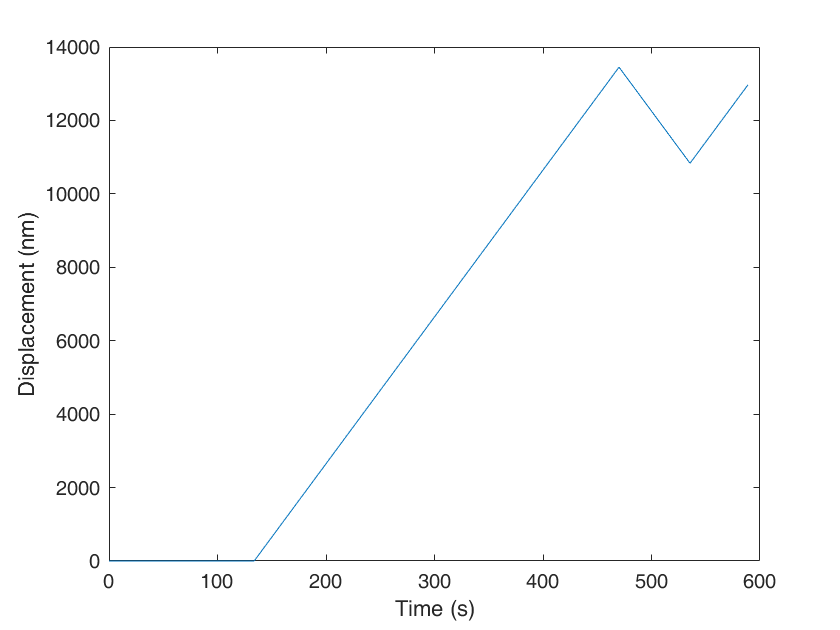

%lipowski sim with unbinding
motorPar.eps0=0.01/60;%single motor unbinding rate s^-1
motorPar.pi0 =0.4/60; %single motor binding rate s^-1
motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.motorConcentration = 1000;%arb units, essentiall scaling of low synthase concentration data here
motorPar.kOn0 = 0.02/60; %rate of single motor (synthase) binding to cargo (mreB) (Guess - waiting for stu data)
motorPar.kOff0 = 0; %rate of single motor (synthase) unbinding from cargo (mreB)
motorPar.Nmax = 1;
motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 10;

%motorDynamics = lipowskiWithUnbindingModel(motorState)

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

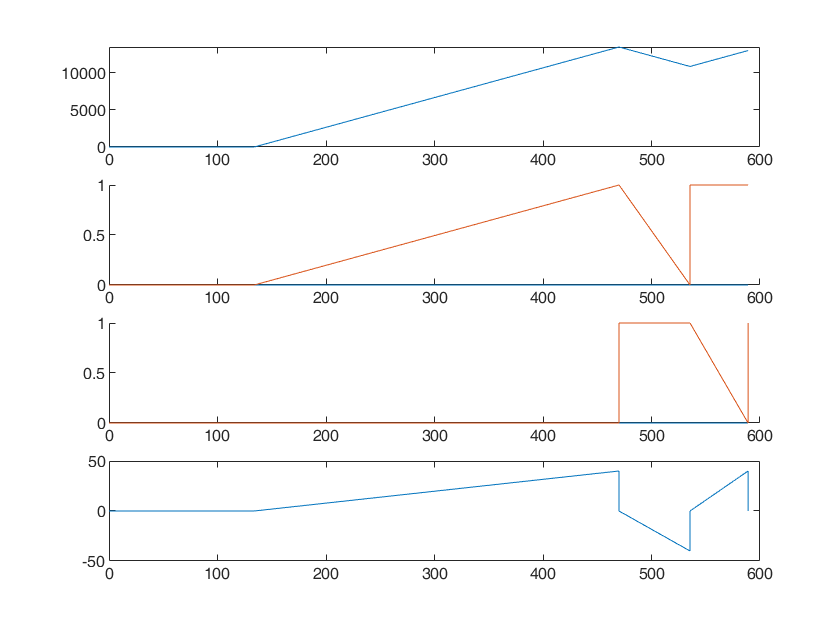

subplot(4,1,1);
plot(t,x);
subplot(4,1,2);
hold all;
plot(t,Nplus);
plot(t,nPlus);
subplot(4,1,3);
hold all
plot(t,Nminus);
plot(t,nMinus);
subplot(4,1,4);
plot(t,vCargo);

%OK The model behaves weirdly even at very high conc and limit to max
%Nmotors = 1 each side - which should recapitulate the stable tug of war
%model